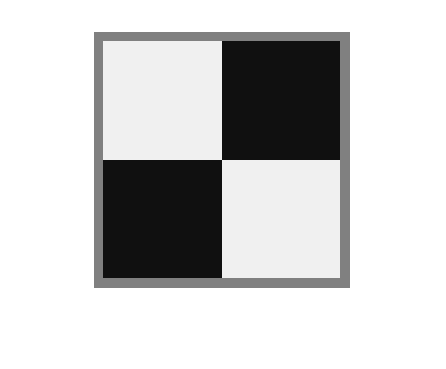

img = imread("input\ps1-input0.png");
imshow(img);

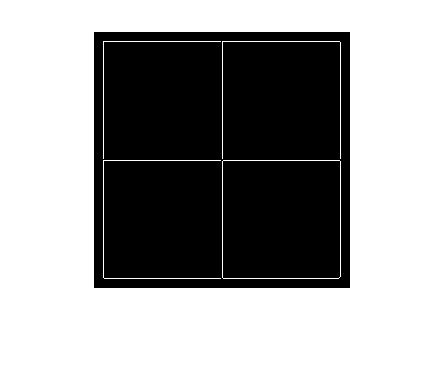

img_edges = edge(img,'Sobel');
imshow(img_edges);






% img = imread("input\ps1-input0.png");
% imshow(img);
% img_edges = edge(img,'log',0,150);
% imshow(img_edges);


maxd = sqrt(size(img_edges,1)^2 + size(img_edges,2)^2)

maxd = 362.0387

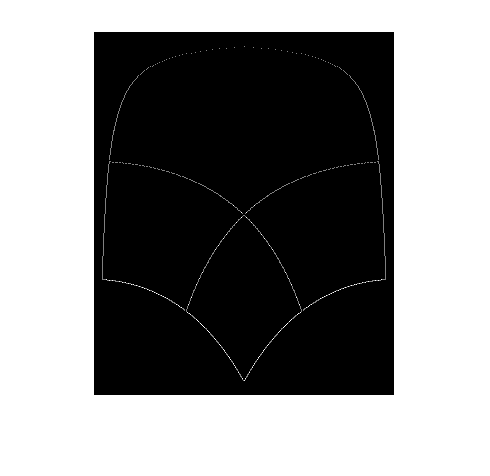

colbins = linspace(0,atan2(1,0), 150);
dbins = linspace(0,maxd, 3);
H = zeros(size(dbins,2),size(colbins,2));
theta_index=1;
for r= 1: size(img_edges,1)
    for c= 1: size(img_edges,2)
        if img_edges(r,c) == 1 
            x=c; y=r;
            angle = atan2(y,x);
            d= x*cos(angle)+y*sin(angle);
            d_index = findbin(dbins, d); 
            %d_index= ceil(x*cos(angle)+y*sin(angle));  
            t_index = findbin(colbins,angle);  
            H(d_index,t_index) = H(d_index,t_index) +  1; 
        end
    end
end
% 


imshow(H,[]);

maxH = max(H(:))

maxH = 2

[maxrowyi , maxcolxi] = find(H >= maxH & H<=maxH);

a = [maxcolxi,maxrowyi]

a =     13   248
    16   249
    19   249
    26   250
    29   251
    32   251
    35   252
    38   253
    40   253
    43   254


marks_image = insertMarker(H, a);
max(H(:))

ans = 2

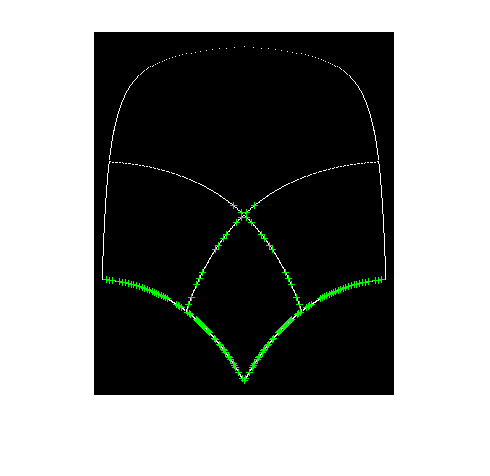

imshow(marks_image,[])

x = 1 : 256;
size(a,1)

ans = 139

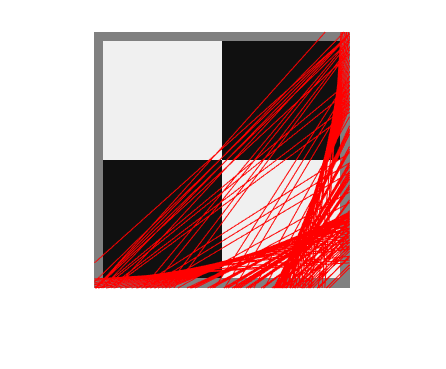

line1


dvalue = 247.0264

tvalue = 0.0630

line2


dvalue = 248.0265

tvalue = 0.0788

line3


dvalue = 248.0265

tvalue = 0.0946

line4


dvalue = 249.0266

tvalue = 0.1313

line5


dvalue = 250.0267

tvalue = 0.1471

line6


dvalue = 250.0267

tvalue = 0.1629

line7


dvalue = 251.0268

tvalue = 0.1786

line8


dvalue = 252.0269

tvalue = 0.1944

line9


dvalue = 252.0269

tvalue = 0.2049

line10


dvalue = 253.0270

tvalue = 0.2206

line11


dvalue = 254.0271

tvalue = 0.2364

line12


dvalue = 255.0272

tvalue = 0.2522

line13


dvalue = 256.0273

tvalue = 0.2627

line14


dvalue = 257.0275

tvalue = 0.2784

line15


dvalue = 258.0276

tvalue = 0.2889

line16


dvalue = 259.0277

tvalue = 0.3047

line17


dvalue = 260.0278

tvalue = 0.3152

line18


dvalue = 261.0279

tvalue = 0.3257

line19


dvalue = 262.0280

tvalue = 0.3362

line20


dvalue = 263.0281

tvalue = 0.3520

line21


dvalue = 264.0282

tvalue = 0.3625

line22


dvalue = 265.0283

tvalue = 0.3730

line23


dvalue = 266.0284

tvalue = 0.3835

line24


dvalue = 272.0291

tvalue = 0.4308

line25


dvalue = 273.0292

tvalue = 0.4413

line26


dvalue = 274.0293

tvalue = 0.4465

line27


dvalue = 275.0294

tvalue = 0.4571

line28


dvalue = 280.0299

tvalue = 0.4886

line29


dvalue = 272.0291

tvalue = 0.4938

line30


dvalue = 281.0300

tvalue = 0.4991

line31


dvalue = 282.0301

tvalue = 0.5043

line32


dvalue = 265.0283

tvalue = 0.5096

line33


dvalue = 252.0269

tvalue = 0.5359

line34


dvalue = 287.0307

tvalue = 0.5359

line35


dvalue = 288.0308

tvalue = 0.5411

line36


dvalue = 289.0309

tvalue = 0.5464

line37


dvalue = 246.0263

tvalue = 0.5516

line38


dvalue = 291.0311

tvalue = 0.5569

line39


dvalue = 292.0312

tvalue = 0.5621

line40


dvalue = 240.0256

tvalue = 0.5674

line41


dvalue = 293.0313

tvalue = 0.5674

line42


dvalue = 294.0314

tvalue = 0.5726

line43


dvalue = 295.0315

tvalue = 0.5779

line44


dvalue = 298.0318

tvalue = 0.5936

line45


dvalue = 299.0319

tvalue = 0.5989

line46


dvalue = 300.0320

tvalue = 0.6042

line47


dvalue = 306.0327

tvalue = 0.6304

line48


dvalue = 217.0232

tvalue = 0.6357

line49


dvalue = 307.0328

tvalue = 0.6357

line50


dvalue = 213.0228

tvalue = 0.6514

line51


dvalue = 312.0333

tvalue = 0.6567

line52


dvalue = 313.0334

tvalue = 0.6619

line53


dvalue = 206.0220

tvalue = 0.6777

line54


dvalue = 317.0339

tvalue = 0.6777

line55


dvalue = 318.0340

tvalue = 0.6830

line56


dvalue = 320.0342

tvalue = 0.6882

line57


dvalue = 202.0216

tvalue = 0.6935

line58


dvalue = 324.0346

tvalue = 0.7040

line59


dvalue = 325.0347

tvalue = 0.7092

line60


dvalue = 327.0349

tvalue = 0.7145

line61


dvalue = 173.0185

tvalue = 0.7302

line62


dvalue = 331.0354

tvalue = 0.7302

line63


dvalue = 333.0356

tvalue = 0.7355

line64


dvalue = 335.0358

tvalue = 0.7407

line65


dvalue = 190.0203

tvalue = 0.7460

line66


dvalue = 340.0363

tvalue = 0.7565

line67


dvalue = 180.0192

tvalue = 0.7723

line68


dvalue = 185.0198

tvalue = 0.7723

line69


dvalue = 346.0370

tvalue = 0.7775

line70


dvalue = 348.0372

tvalue = 0.7880

line71


dvalue = 346.0370

tvalue = 0.7933

line72


dvalue = 180.0192

tvalue = 0.7985

line73


dvalue = 185.0198

tvalue = 0.7985

line74


dvalue = 340.0363

tvalue = 0.8143

line75


dvalue = 190.0203

tvalue = 0.8248

line76


dvalue = 335.0358

tvalue = 0.8301

line77


dvalue = 333.0356

tvalue = 0.8353

line78


dvalue = 173.0185

tvalue = 0.8406

line79


dvalue = 331.0354

tvalue = 0.8406

line80


dvalue = 327.0349

tvalue = 0.8563

line81


dvalue = 325.0347

tvalue = 0.8616

line82


dvalue = 324.0346

tvalue = 0.8668

line83


dvalue = 202.0216

tvalue = 0.8773

line84


dvalue = 320.0342

tvalue = 0.8826

line85


dvalue = 318.0340

tvalue = 0.8878

line86


dvalue = 206.0220

tvalue = 0.8931

line87


dvalue = 317.0339

tvalue = 0.8931

line88


dvalue = 313.0334

tvalue = 0.9089

line89


dvalue = 312.0333

tvalue = 0.9141

line90


dvalue = 213.0228

tvalue = 0.9194

line91


dvalue = 217.0232

tvalue = 0.9351

line92


dvalue = 307.0328

tvalue = 0.9351

line93


dvalue = 306.0327

tvalue = 0.9404

line94


dvalue = 300.0320

tvalue = 0.9666

line95


dvalue = 299.0319

tvalue = 0.9719

line96


dvalue = 298.0318

tvalue = 0.9772

line97


dvalue = 295.0315

tvalue = 0.9929

line98


dvalue = 294.0314

tvalue = 0.9982

line99


dvalue = 240.0256

tvalue = 1.0034

line100


dvalue = 293.0313

tvalue = 1.0034

line101


dvalue = 292.0312

tvalue = 1.0087

line102


dvalue = 291.0311

tvalue = 1.0139

line103


dvalue = 246.0263

tvalue = 1.0192

line104


dvalue = 289.0309

tvalue = 1.0244

line105


dvalue = 288.0308

tvalue = 1.0297

line106


dvalue = 252.0269

tvalue = 1.0349

line107


dvalue = 287.0307

tvalue = 1.0349

line108


dvalue = 265.0283

tvalue = 1.0612

line109


dvalue = 282.0301

tvalue = 1.0665

line110


dvalue = 281.0300

tvalue = 1.0717

line111


dvalue = 272.0291

tvalue = 1.0770

line112


dvalue = 280.0299

tvalue = 1.0822

line113


dvalue = 275.0294

tvalue = 1.1137

line114


dvalue = 274.0293

tvalue = 1.1242

line115


dvalue = 273.0292

tvalue = 1.1295

line116


dvalue = 272.0291

tvalue = 1.1400

line117


dvalue = 266.0284

tvalue = 1.1873

line118


dvalue = 265.0283

tvalue = 1.1978

line119


dvalue = 264.0282

tvalue = 1.2083

line120


dvalue = 263.0281

tvalue = 1.2188

line121


dvalue = 262.0280

tvalue = 1.2346

line122


dvalue = 261.0279

tvalue = 1.2451

line123


dvalue = 260.0278

tvalue = 1.2556

line124


dvalue = 259.0277

tvalue = 1.2661

line125


dvalue = 258.0276

tvalue = 1.2819

line126


dvalue = 257.0275

tvalue = 1.2924

line127


dvalue = 256.0273

tvalue = 1.3081

line128


dvalue = 255.0272

tvalue = 1.3186

line129


dvalue = 254.0271

tvalue = 1.3344

line130


dvalue = 253.0270

tvalue = 1.3501

line131


dvalue = 252.0269

tvalue = 1.3659

line132


dvalue = 252.0269

tvalue = 1.3764

line133


dvalue = 251.0268

tvalue = 1.3922

line134


dvalue = 250.0267

tvalue = 1.4079

line135


dvalue = 250.0267

tvalue = 1.4237

line136


dvalue = 249.0266

tvalue = 1.4395

line137


dvalue = 248.0265

tvalue = 1.4762

line138


dvalue = 248.0265

tvalue = 1.4920

line139


dvalue = 247.0264

tvalue = 1.5078

imshow(img)
for i = 1:size(a,1)
    disp("line"+i);
    dvalue = dbins(a(i,2))
%     dvalue = a(i,2);
    tvalue = colbins(a(i,1))
    line(x,(dvalue-x*cos(tvalue))/sin(tvalue), 'color','r')
end

% a
% dmax1 = 265; 
% thetamax1 = colbins(1,25);
% dmax2 = 267; 
% thetamax2 = colbins(1,26);
% dmax3 = 184; 
% thetamax2 = 
% % dmaix
% % thetamax1 = colbins(1,51);
% % dmax1 = 184;
% % 
% % y1 = (dmax1 - x*cos(thetamax1))/sin(thetamax1);
% % y2 = (dmax2 - x*cos(thetamax2))/sin(thetamax2);
% % y3 = (dmax3 - x*cos(thetamax3))/sin(thetamax3);
% % y4 = (dmax4 - x*cos(thetamax4))/sin(thetamax4);
% % y5 = (dmax5 - x*cos(thetamax5))/sin(thetamax5);
% imshow(img)
% line(x,y1, 'color','r');
% line([1 256],[200 200], 'color','r');
% max(H(:))
% thetamax= atan2(maxrowyi, maxcolxi)
% dmax = maxcolxi*cos(thetamax)+maxrowyi*sin(thetamax)
% 
% 
% x = 0 : 256;
% m = -cos(thetamax)/sin(thetamax);
% b = dmax/sin(thetamax);
% y = m*x+b; 
%  figure(1)
% plot(x, y)
%  grid
%  axis([0  5    0  12])

%  
% x = 0 : 5;
% m = 2;
% b = 1;
% y = m*x + b;
% figure(1)
% plot(x, y)
% % grid
% % axis([0  5    0  12])

% x = 0:pi/100:2*pi;
% y = sin(x);
% plot(x,y)
